#### Modeling of a RRR spatial robot / Моделирование пространственного  робота RRP

clear; clc;
% to clear the workspace and command window 
% чтобы очистить рабочее пространство и окно команд
format short;
addpath('C:\Users\Arti_Eg\Documents\work\Sber\casadi-windows-matlabR2016a-v3.5.5')

import casadi.*

Variables / Переменные

$q_1, \; q_2, \; q_3  $ are the angles of rotations, $dq_1, \; dq_2, \; dq_3  $ are the angular velocities,  $f_x, \; f_y, \; f_z$ are external load

$q_1, \; q_2, \; q_3  $ являются углами поворота, $dq_1, \; dq_2, \; dq_3  $являются угловыми скоростями,  $f_x, \; f_y, \; f_z$ являются внешней нагрузкой

$l_1,\; l_2, \; l_3$ are lengths, $m_1, \;  m_2, \; m_3 $ are masses, $j_{x_1}, j_{y_1}, j_{z_1}, j_{x_2}, j_{y_2}, j_{z_2}, j_{x_3}, j_{y_3}, j_{z_3} $ are inertias, and $g$ is gravity constant

$l_1,\; l_2, \; l_3$ длины, $m_1, \;  m_2, \; m_3 $ массы, $j_{x_1}, j_{y_1}, j_{z_1}, j_{x_2}, j_{y_2}, j_{z_2}, j_{x_3}, j_{y_3}, j_{z_3} $ инерции, and $g$ гравитационная постоянная

l0x = 0.5;l0y = 0.1; l1z = 0.1; l2z = 0.1; l3z = 0.1;
l0cx = 0.25;l0cy = 0.09; l1cz = 0.01; l2cz = 0.01; l3cz = 0.01;

Generalized coordinates are the angles of rotations, dq stands for the angular velocities / Обобщенные координаты - это углы поворота, dq обозначает угловые скорости

q =SX.sym('q',3)

q = [q_0, q_1, q_2]

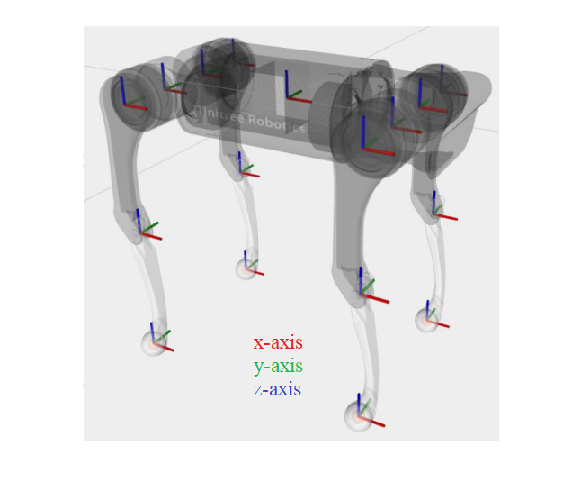

dq =SX.sym('dq',3);
ddq =SX.sym('ddq',3);
imshow('ident_manip.png')

Vectors of unit angular velocities / Векторы единичных угловых скоростей

w1=SX.zeros(3,1);
w2=SX.zeros(3,1);
w3=SX.zeros(3,1);
w1(1,1) = 1; % x-rotation axis
w2(2,1) = 1; % y-rotation axis
w3(2,1) = 1; % y-rotation axis
w3

w3 = @1=0, [@1, 1, @1]

Positon of joints / Расположение сочленений (радиусы векторы до солченений от frame)

r1=SX.zeros(3,1);
r2=SX.zeros(3,1);
r3=SX.zeros(3,1);
r1(1,1) = l0x;
r1(2,1) = l0y;
r2(3,1) = l1z;
r2 = r1 + r2;
r3(3,1) = l2z;
r3 = r3 + r2;
r1

r1 = [0.5, 0.1, 0]

w = SX.sym('w',3,1);
T =SX(3,3);
T(1,2) = -w(3);
T(1,3) =  w(2);
T(2,3) = -w(1);
T(2,1) = w(3);
T(3,1) =  -w(2);
T(3,2) = w(1);

VecToso3 = Function('f',{w},{T}); %  VecToso3 is a function for skew-symmetric representation

Vectors of translation motion / Векторы поступательного движения

v1_unit=-VecToso3(w1)*r1; 
v2_unit=-VecToso3(w2)*r2;
v3_unit=-VecToso3(w3)*r3 

v3_unit = [-0.2, 0, 0.5]

Home position of CoM and ee / Изначальные положения для центром масс и энд-эффектора

Here by Hc10 I have denoted $H_{c_1}^{0}$. Тут под Hc10 понимается $H_{c_1}^{0}$

ad = SX(1,4);
ad(1,4)=1;
r1c=SX.zeros(3,1);
r2c=SX.zeros(3,1);
r3c=SX.zeros(3,1);
r4=SX.zeros(3,1);
r1c(1,1) = l0cx;
r1c(2,1) = l0cy;
r2c(3,1) = l1cz;
r2c = r1 + r2c;
r3c(3,1) = l2cz;
r3c = r2 + r3c

r3c = [0.5, 0.1, 0.11]

r4(3,1) = l3z;
r2c

r2c = [0.5, 0.1, 0.01]

Hc10_home=[SX.eye(3), r1c; ad]

Hc10_home = @1=1, 
[[@1, 00, 00, 0.25], 
 [00, @1, 00, 0.09], 
 [00, 00, @1, 0], 
 [00, 00, 00, @1]]

Hc20_home=[SX.eye(3), r2c; ad];
Hc30_home=[SX.eye(3), r3c; ad];
Hee0_home=[SX.eye(3), r4; ad]

Hee0_home = @1=1, @2=0, 
[[@1, 00, 00, @2], 
 [00, @1, 00, @2], 
 [00, 00, @1, 0.1], 
 [00, 00, 00, @1]]

#### Rotation matrixes / Матрицы поворота


$$R=e^{\tilde{w}}=I+\tilde{w}\sin{\theta}+\tilde{w}^2(1-\cos{\theta})$$


In code by Rij I have denoted $R_i^j$ 

R10=SX.eye(3)+VecToso3(w1)*sin(q(1))+VecToso3(w1)^2*(1-cos(q(1))) % matrix exponential rodrigues formula

R10 = @1=1, @2=0, @3=(@1-cos(q_0)), @4=sin(q_0), 
[[@1, @2, @2], 
 [@2, (@1-@3), (-@4)], 
 [@2, @4, (@1-@3)]]

R21=SX.eye(3)+VecToso3(w2)*sin(q(2))+VecToso3(w2)^2*(1-cos(q(2))) ;
R32=SX.eye(3)+VecToso3(w3)*sin(q(3))+VecToso3(w3)^2*(1-cos(q(3))) ;


% m1 m2 m3 jx1 jy1 jz1 jx2 jy2 jz2 jx3 jy3 jz3 g 

addpath('mr'); % we use function library by Kevin Lynch / мы используем библиотеку функций Кевина Линча

Generalized coordinates are the angles of rotations, dq stands for the angular velocities / Обобщенные координаты - это углы поворота, dq обозначает угловые скорости

q = [q1, q2, q3]; 
dq = [dq1, dq2, dq3];

Vectors of unit angular velocities / Векторы единичных угловых скоростей

w1=[0;0;1];
w2=[0;0;0];
w3=[0;0;0]; % there is no rotation for the prismatic joint

Positon of joints / Расположение сочленений (радиусы векторы до солченений от frame)

r1=[0;0;0];
r2=[0;0;l1];
r3=[l2/2;0;l1];

Vectors of translation motion / Векторы поступательного движения

v1_unit=-VecToso3(w1)*r1; 
% VecToso3 is a function from mr for skew-symmetric representation
% VecToso3 является функцией из mr для кососимметричного представления
v2_unit=[1;0;0];
v3_unit=[0;0;1]; % prismatic joint along z axis

Unit twists or screws the links / Винтовые оси для звеньев

S1=[w1;v1_unit];
S2=[w2;v2_unit];
S3=[w3;v3_unit];

Home position of CoM and ee / Изначальные положения для центром масс и энд-эффектора

Here by Hc10 I have denoted $H_{c_1}^{0}$. Тут под Hc10 понимается $H_{c_1}^{0}$

Hc10_home=[eye(3,3), [0;0;l1/2];  0,0,0,1]

$$Hc10\_home = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & \frac{l_{1}}{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Hc20_home=[eye(3,3), [0;0;l1];  0,0,0,1]

$$Hc20\_home = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Hc30_home=[eye(3,3), [l2/2;0;l1];  0,0,0,1]

$$Hc30\_home = \left(\begin{array}{cccc} 1 & 0 & 0 & \frac{l_{2}}{2}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Hee0_home=[eye(3,3), [l2/2;0;l1-l3/2];  0,0,0,1]

$$Hee0\_home = \left(\begin{array}{cccc} 1 & 0 & 0 & \frac{l_{2}}{2}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & l_{1}-\frac{l_{3}}{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

#### Rotation matrixes / Матрицы поворота


$$R=e^{\tilde{w}}=I+\tilde{w}\sin{\theta}+\tilde{w}^2(1-\cos{\theta})$$


In code by Rij I have denoted $R_i^j$ / В коде под Rij я обозначил$R_i^j$

R10=eye(3,3)+VecToso3(w1)*sin(q1)+VecToso3(w1)^2*(1-cos(q1)) % matrix exponential rodrigues formula

$$R10 = \left(\begin{array}{ccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R21=eye(3,3)+VecToso3(w2)*sin(q2)+VecToso3(w2)^2*(1-cos(q2)) ;
R32=eye(3,3)+VecToso3(w3)*sin(q3)+VecToso3(w3)^2*(1-cos(q3)) ;

#### Homogeneous transformation matrixes / Однородная матрица преобразования 

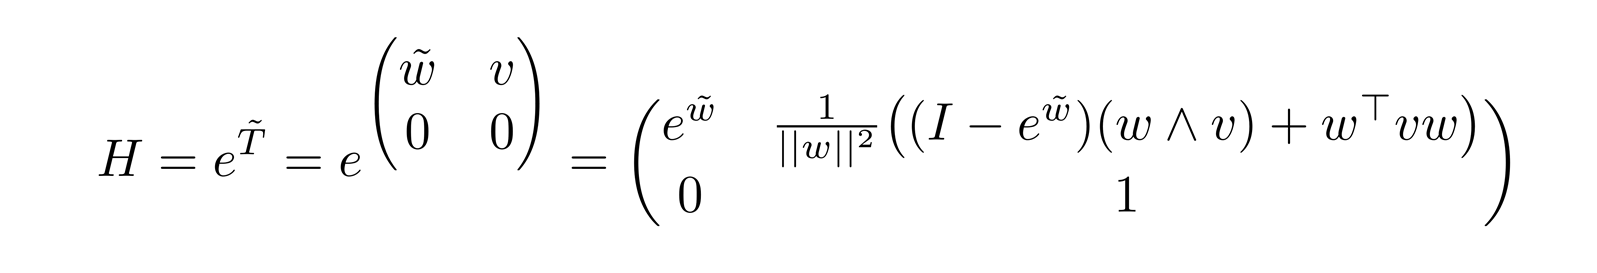

abs_ter_1=(eye(3,3)*q1+(1-cos(q1))*VecToso3(w1)+(q1-sin(q1))*VecToso3(w1)^2)*v1_unit;
abs_ter_2=(eye(3,3)*q2+(1-cos(q2))*VecToso3(w2)+(q2-sin(q2))*VecToso3(w2)^2)*v2_unit;
abs_ter_3=(eye(3,3)*q3+(1-cos(q3))*VecToso3(w3)+(q3-sin(q3))*VecToso3(w3)^2)*v3_unit;

Here by T100 I have denoted $T_1^{0,0}$

e_T100q1=[R10, abs_ter_1; 0,0,0,1]

$$e\_T100q1 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

e_T201q2=[R21, abs_ter_2; 0,0,0,1];
e_T302q3=[R32, abs_ter_3; 0,0,0,1];

#### Direct kinematics / Прямая кинематика


$$H_n^0 (q_1, q_2, \dots q_n)=
e^{\tilde{\hat{T}}_1^{0,0}q_1} e^{\tilde{\hat{T}}_2^{0,1}q_2} \dots
e^{\tilde{\hat{T}}_n^{0,(n-1)}q_n} H_n^{0}(0),
$$


Hc10=simplify(e_T100q1*Hc10_home);
Hc20=simplify(e_T100q1*e_T201q2*Hc20_home);
Hc30=simplify(e_T100q1*e_T201q2*e_T302q3*Hc30_home);
Hee0=simplify(e_T100q1*e_T201q2*e_T302q3*Hee0_home);
P=Hee0*[0;0;0;1]

$$P = \left(\begin{array}{c} \frac{\cos\left(q_{1}\right)\,\left(l_{2}+2\,q_{2}\right)}{2}\\ \frac{\sin\left(q_{1}\right)\,\left(l_{2}+2\,q_{2}\right)}{2}\\ l_{1}-\frac{l_{3}}{2}+q_{3}\\ 1 \end{array}\right)$$


Hc01=TransInv(Hc10);
Hc02=TransInv(Hc20);
Hc03=TransInv(Hc30);
H0ee=TransInv(Hee0)

$$H0ee = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & \sin\left(q_{1}\right) & 0 & -\frac{{\cos\left(q_{1}\right)}^{2}\,\left(l_{2}+2\,q_{2}\right)}{2}-\frac{{\sin\left(q_{1}\right)}^{2}\,\left(l_{2}+2\,q_{2}\right)}{2}\\ -\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & 0\\ 0 & 0 & 1 & \frac{l_{3}}{2}-l_{1}-q_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

TransInv is a function from mr to take an inverse of H / TransInv - это функция от mr чтобы брать обратную от  H

#### Geometriacal Jacobians / Геометрические матрицы якоби

J1=S1;
J2=simplify(Adjoint(e_T100q1*e_T201q2)*S2);
J3=simplify(Adjoint(e_T100q1*e_T201q2*e_T302q3)*S3);
J_1=[J1, zeros(6,1), zeros(6,1)];
J_2=[J1, J2, zeros(6,1)];
J_3=[J1, J2, J3]

$$J\_3 = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 1 & 0 & 0\\ 0 & \cos\left(q_{1}\right) & 0\\ 0 & \sin\left(q_{1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

Coordinates of CoM / z координаты центров масс

zc1=[0, 0, 1, 0]*Hc10*[0;0;0;1];
zc2=[0, 0, 1, 0]*Hc20*[0;0;0;1];
zc3=[0, 0, 1, 0]*Hc30*[0;0;0;1]

$$zc3 = l_{1}+q_{3}$$

Inertia / инерция

j1=[jx1, 0, 0; 0, jy1, 0; 0, 0, jz1];
j2=[jx2, 0, 0; 0, jy2, 0; 0, 0, jz2];
j3=[jx3, 0, 0; 0, jy3, 0; 0, 0, jz3];
I1=[j1, zeros(3,3); zeros(3,3), eye(3,3)*m1];
I2=[j2, zeros(3,3); zeros(3,3), eye(3,3)*m2];
I3=[j3, zeros(3,3); zeros(3,3), eye(3,3)*m3]

$$I3 = \left(\begin{array}{cccccc} {\mathrm{jx}}_{3} & 0 & 0 & 0 & 0 & 0\\ 0 & {\mathrm{jy}}_{3} & 0 & 0 & 0 & 0\\ 0 & 0 & {\mathrm{jz}}_{3} & 0 & 0 & 0\\ 0 & 0 & 0 & m_{3} & 0 & 0\\ 0 & 0 & 0 & 0 & m_{3} & 0\\ 0 & 0 & 0 & 0 & 0 & m_{3} \end{array}\right)$$

#### Mass matrix and other terms of dynamic equation / Матрица массы и другие члены динамического уравнения

M_1 = simplify(J_1.'*Adjoint(Hc01).'*I1*Adjoint(Hc01)*J_1);
M_2 = simplify(J_2.'*Adjoint(Hc02).'*I2*Adjoint(Hc02)*J_2);
M_3 = simplify(J_3.'*Adjoint(Hc03).'*I3*Adjoint(Hc03)*J_3);
M = M_1+M_2+M_3

$$M = \left(\begin{array}{ccc} {\mathrm{jz}}_{1}+{\mathrm{jz}}_{2}+{\mathrm{jz}}_{3}+\frac{{l_{2}}^{2}\,m_{3}}{4}+m_{2}\,{q_{2}}^{2}+m_{3}\,{q_{2}}^{2}+l_{2}\,m_{3}\,q_{2} & 0 & 0\\ 0 & m_{2}+m_{3} & 0\\ 0 & 0 & m_{3} \end{array}\right)$$

V = simplify(m1*g*zc1+m2*g*zc2+m3*g*zc3);
N = simplify([diff(V,q1); diff(V,q2); diff(V,q3)])

$$N = \left(\begin{array}{c} 0\\ 0\\ g\,m_{3} \end{array}\right)$$

C = simplify(getC(M, q ,dq))

$$C = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

Wrench / Пространственный ко-вектор внешней нагрузки

W = [0, 0, 0, fx, fy, fz];

Joints' torque / Момент на сочленениях

tau = simplify(J_3.'*Adjoint(H0ee).'*W.')

$$tau = \left(\begin{array}{c} \mathrm{fy}\,\left(\frac{l_{2}}{2}+q_{2}\right)\\ \mathrm{fx}\\ \mathrm{fz} \end{array}\right)$$

function [C] = getC(M, q, dq)

    n = size(M, 1);
    G = sym(zeros(n, n, n)); % cristofil symbol G_ijk
   
    for i = 1:n
        for j = 1:n
            for k = 1:n
                G(i, j, k) =  sym(1/2) * (diff(M(i, j), q(k)) + diff(M(i, k), q(j)) - diff(M(k, j), q(i)));
            end
        end
    end

    C = sym(zeros(n, 1)); % coriolis and centrifugal C = \sum c_{ijk} \dot{q}_i
         for j = 1:n
            sum = 0;
            for k = 1:n
                sum = sum + G(i, j, k) * dq(k);
         end
    C(j) = sum;
    end
end